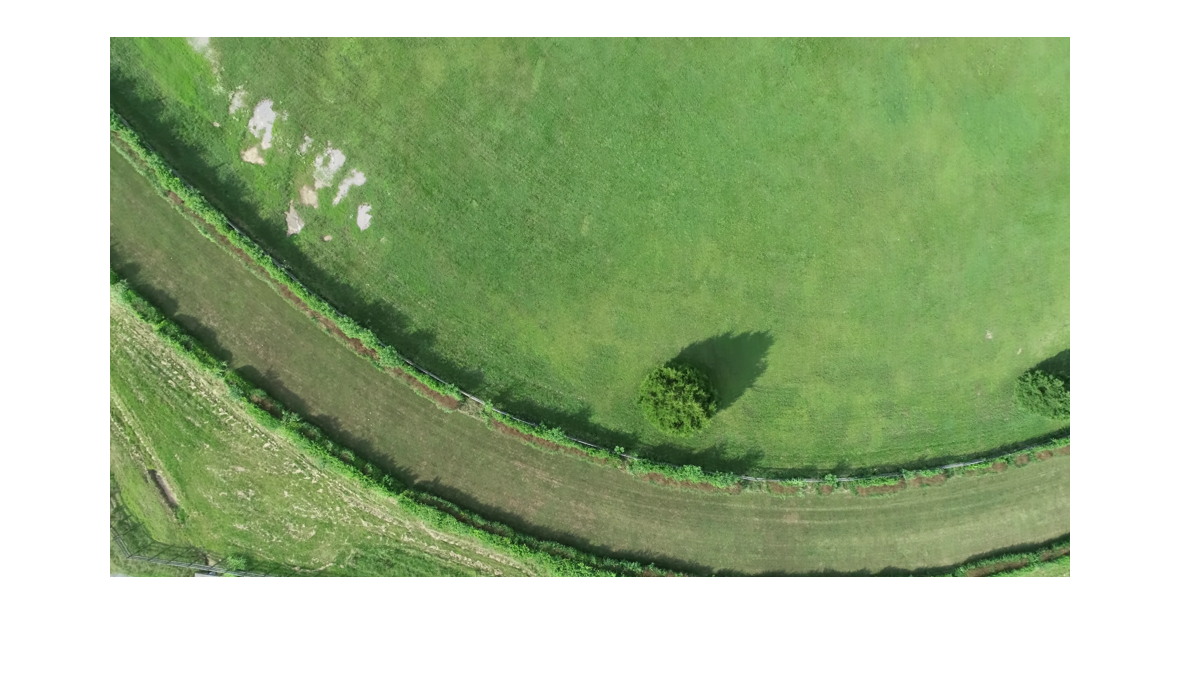

A = imread('TestImages/Nashville/Frame17.png');
A = imresize(A,0.25);
Agray = rgb2gray(A);
figure
imshow(A)

imageSize = size(A);
numRows = imageSize(1);
numCols = imageSize(2);

wavelengthMin = 4/sqrt(2);
wavelengthMax = hypot(numRows,numCols);
n = floor(log2(wavelengthMax/wavelengthMin));
wavelength = 2.^(0:(n-2)) * wavelengthMin;

deltaTheta = 45;
orientation = 0:deltaTheta:(180-deltaTheta);

g = gabor(wavelength,orientation);

gabormag = imgaborfilt(Agray,g);

for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    K = 3;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),K*sigma); 
end

X = 1:numCols;
Y = 1:numRows;
[X,Y] = meshgrid(X,Y);
featureSet = cat(3,gabormag,X);
featureSet = cat(3,featureSet,Y);

disp(size(featureSet))

numPoints = numRows*numCols;
X = reshape(featureSet,numRows*numCols,[]);

X = bsxfun(@minus, X, mean(X));
X = bsxfun(@rdivide,X,std(X));

coeff = pca(X);
feature2DImage = reshape(X*coeff(:,1),numRows,numCols);
figure
imshow(feature2DImage,[])

L = kmeans(X,2,'Replicates',5);

L = reshape(L,[numRows numCols]);
figure
imshow(label2rgb(L))

L1 = kmeans(X,3,'Replicates',5);

L1 = reshape(L1,[numRows numCols]);
figure
imshow(label2rgb(L))